% Base
% Copyright (c) 2015, Yarpiz (www.yarpiz.com)
% All rights reserved. Please read the "license.txt" for license terms.
%
% Project Code: YPEA120
% Project Title: Non-dominated Sorting Genetic Algorithm II (NSGA-II)
% Publisher: Yarpiz (www.yarpiz.com)
% 
% Developer: S. Mostapha Kalami Heris (Member of Yarpiz Team)
% 
% Contact Info: sm.kalami@gmail.com, info@yarpiz.com
%
% Weiguang Chen
% Contact Info: chen2621978@163.com
%

clc;
clear;
close all;


## Problem Definition

CostFunction=@(x) MOP4(x);      % Cost Function % 解决的问题
nVar= 3;             % Number of Decision Variables %自变量个数
VarMin= -5;          % Lower Bound of Variables %自变量的下限
VarMax= 5;          % Upper Bound of Variables %自变量的上限

VarSize=[1 nVar];   % Size of Decision Variables Matrix

% Number of Objective Functions
nObj=numel(CostFunction(unifrnd(VarMin,VarMax,VarSize)));

##  Parameters

MaxIt = 200;      % Maximum Number of Iterations

nPop = 50;        % Population Size

pCrossover = 0.7;                         % Crossover Percentage
nCrossover = 2*round(pCrossover*nPop/2);  % Number of Parnets (Offsprings)

pMutation = 0.4;                          % Mutation Percentage
nMutation = round(pMutation*nPop);        % Number of Mutants

mu = 0.02;                    % Mutation Rate

sigma = 0.1*(VarMax-VarMin);  % Mutation Step Size

rou = 1;
rouMax = 1;
rouMin = 0.1;

Info.nVar = nVar;
Info.VarMin = VarMin;
Info.VarMax = VarMax;
Info.nObj = nObj;
Info.k = 4; %聚类数
Info.nPop = nPop;

## Initialization

empty_individual.Position=[];
empty_individual.Cost=[];
empty_individual.Rank=[];
empty_individual.DominationSet=[];
empty_individual.DominatedCount=[];
empty_individual.CrowdingDistance=[];

% Jam
empty_individual.GDistion = [];
empty_individual.FSorting = [];


pop=repmat(empty_individual,nPop,1);

for i=1:nPop
    
    pop(i).Position=unifrnd(VarMin,VarMax,VarSize);
    
    pop(i).Cost=CostFunction(pop(i).Position);
    
end

% Jam
   pop = CalcGDRegressDistance(pop, Info);

% % Non-Dominated Sorting
% [pop, F]=NonDominatedSorting(pop);
% 
% % Calculate Crowding Distance
% pop=CalcCrowdingDistance(pop,F);
% 
% % Sort Population
% [pop, F]=SortPopulation(pop);

##  Main Loop

Iteration 1: Number of F1 Members = 8
Iteration 2: Number of F1 Members = 5
Iteration 3: Number of F1 Members = 4
Iteration 4: Number of F1 Members = 9
Iteration 5: Number of F1 Members = 14
Iteration 6: Number of F1 Members = 26
Iteration 7: Number of F1 Members = 32
Iteration 8: Number of F1 Members = 29
Iteration 9: Number of F1 Members = 43


Iteration 10: Number of F1 Members = 50
Iteration 11: Number of F1 Members = 50
Iteration 12: Number of F1 Members = 50


Iteration 13: Number of F1 Members = 50


Iteration 14: Number of F1 Members = 50


Iteration 15: Number of F1 Members = 50
Iteration 16: Number of F1 Members = 50
Iteration 17: Number of F1 Members = 50


Iteration 18: Number of F1 Members = 50


Iteration 19: Number of F1 Members = 50


Iteration 20: Number of F1 Members = 50


Iteration 21: Number of F1 Members = 50


Iteration 22: Number of F1 Members = 50


Iteration 23: Number of F1 Members = 50


Iteration 24: Number of F1 Members = 50


Iteration 25: Number of F1 Members = 50


Iteration 26: Number of F1 Members = 50


Iteration 27: Number of F1 Members = 50


Iteration 28: Number of F1 Members = 50


Iteration 29: Number of F1 Members = 50


Iteration 30: Number of F1 Members = 50


Iteration 31: Number of F1 Members = 50


Iteration 32: Number of F1 Members = 50


Iteration 33: Number of F1 Members = 50


Iteration 34: Number of F1 Members = 50


Iteration 35: Number of F1 Members = 50


Iteration 36: Number of F1 Members = 50


Iteration 37: Number of F1 Members = 50


Iteration 38: Number of F1 Members = 50


Iteration 39: Number of F1 Members = 50


Iteration 40: Number of F1 Members = 50


Iteration 41: Number of F1 Members = 50


Iteration 42: Number of F1 Members = 50


Iteration 43: Number of F1 Members = 50


Iteration 44: Number of F1 Members = 50


Iteration 45: Number of F1 Members = 50


Iteration 46: Number of F1 Members = 50


Iteration 47: Number of F1 Members = 50


Iteration 48: Number of F1 Members = 50


Iteration 49: Number of F1 Members = 50


Iteration 50: Number of F1 Members = 50


Iteration 51: Number of F1 Members = 50


Iteration 52: Number of F1 Members = 50


Iteration 53: Number of F1 Members = 50


Iteration 54: Number of F1 Members = 50


Iteration 55: Number of F1 Members = 50


Iteration 56: Number of F1 Members = 50


Iteration 57: Number of F1 Members = 50


Iteration 58: Number of F1 Members = 50


Iteration 59: Number of F1 Members = 50


Iteration 60: Number of F1 Members = 50


Iteration 61: Number of F1 Members = 50


Iteration 62: Number of F1 Members = 50


Iteration 63: Number of F1 Members = 50
Iteration 64: Number of F1 Members = 50


Iteration 65: Number of F1 Members = 50


Iteration 66: Number of F1 Members = 50


Iteration 67: Number of F1 Members = 50


Iteration 68: Number of F1 Members = 50


Iteration 69: Number of F1 Members = 50


Iteration 70: Number of F1 Members = 50


Iteration 71: Number of F1 Members = 50


Iteration 72: Number of F1 Members = 50
Iteration 73: Number of F1 Members = 50
Iteration 74: Number of F1 Members = 50
Iteration 75: Number of F1 Members = 50
Iteration 76: Number of F1 Members = 50


Iteration 77: Number of F1 Members = 50
Iteration 78: Number of F1 Members = 50


Iteration 79: Number of F1 Members = 50


Iteration 80: Number of F1 Members = 50
Iteration 81: Number of F1 Members = 50
Iteration 82: Number of F1 Members = 50
Iteration 83: Number of F1 Members = 50


Iteration 84: Number of F1 Members = 50


Iteration 85: Number of F1 Members = 50


Iteration 86: Number of F1 Members = 50
Iteration 87: Number of F1 Members = 50
Iteration 88: Number of F1 Members = 50


Iteration 89: Number of F1 Members = 50


Iteration 90: Number of F1 Members = 50


Iteration 91: Number of F1 Members = 50


Iteration 92: Number of F1 Members = 50


Iteration 93: Number of F1 Members = 50


Iteration 94: Number of F1 Members = 50


Iteration 95: Number of F1 Members = 50


Iteration 96: Number of F1 Members = 50


Iteration 97: Number of F1 Members = 50


Iteration 98: Number of F1 Members = 50


Iteration 99: Number of F1 Members = 50


Iteration 100: Number of F1 Members = 50


Iteration 101: Number of F1 Members = 50
Iteration 102: Number of F1 Members = 50
Iteration 103: Number of F1 Members = 50


Iteration 104: Number of F1 Members = 50


Iteration 105: Number of F1 Members = 50


Iteration 106: Number of F1 Members = 50


Iteration 107: Number of F1 Members = 50


Iteration 108: Number of F1 Members = 50


Iteration 109: Number of F1 Members = 50


Iteration 110: Number of F1 Members = 50
Iteration 111: Number of F1 Members = 50


Iteration 112: Number of F1 Members = 50
Iteration 113: Number of F1 Members = 50


Iteration 114: Number of F1 Members = 50


Iteration 115: Number of F1 Members = 50


Iteration 116: Number of F1 Members = 50
Iteration 117: Number of F1 Members = 50


Iteration 118: Number of F1 Members = 50
Iteration 119: Number of F1 Members = 50


Iteration 120: Number of F1 Members = 50


Iteration 121: Number of F1 Members = 50


Iteration 122: Number of F1 Members = 50


Iteration 123: Number of F1 Members = 50
Iteration 124: Number of F1 Members = 50


Iteration 125: Number of F1 Members = 50


Iteration 126: Number of F1 Members = 50
Iteration 127: Number of F1 Members = 50


Iteration 128: Number of F1 Members = 50


Iteration 129: Number of F1 Members = 50


Iteration 130: Number of F1 Members = 50


Iteration 131: Number of F1 Members = 50
Iteration 132: Number of F1 Members = 50


Iteration 133: Number of F1 Members = 50


Iteration 134: Number of F1 Members = 50


Iteration 135: Number of F1 Members = 50


Iteration 136: Number of F1 Members = 50


Iteration 137: Number of F1 Members = 50
Iteration 138: Number of F1 Members = 50


Iteration 139: Number of F1 Members = 50
Iteration 140: Number of F1 Members = 50


Iteration 141: Number of F1 Members = 50


Iteration 142: Number of F1 Members = 50
Iteration 143: Number of F1 Members = 50


Iteration 144: Number of F1 Members = 50


Iteration 145: Number of F1 Members = 50


Iteration 146: Number of F1 Members = 50


Iteration 147: Number of F1 Members = 50
Iteration 148: Number of F1 Members = 50


Iteration 149: Number of F1 Members = 50


Iteration 150: Number of F1 Members = 50
Iteration 151: Number of F1 Members = 50


Iteration 152: Number of F1 Members = 50


Iteration 153: Number of F1 Members = 50


Iteration 154: Number of F1 Members = 50
Iteration 155: Number of F1 Members = 50


Iteration 156: Number of F1 Members = 50
Iteration 157: Number of F1 Members = 50
Iteration 158: Number of F1 Members = 50
Iteration 159: Number of F1 Members = 50


Iteration 160: Number of F1 Members = 50


Iteration 161: Number of F1 Members = 50


Iteration 162: Number of F1 Members = 50
Iteration 163: Number of F1 Members = 50


Iteration 164: Number of F1 Members = 50


Iteration 165: Number of F1 Members = 50


Iteration 166: Number of F1 Members = 50


Iteration 167: Number of F1 Members = 50


Iteration 168: Number of F1 Members = 50


Iteration 169: Number of F1 Members = 50


Iteration 170: Number of F1 Members = 50
Iteration 171: Number of F1 Members = 50


Iteration 172: Number of F1 Members = 50


Iteration 173: Number of F1 Members = 50


Iteration 174: Number of F1 Members = 50
Iteration 175: Number of F1 Members = 50


Iteration 176: Number of F1 Members = 50
Iteration 177: Number of F1 Members = 50
Iteration 178: Number of F1 Members = 50


Iteration 179: Number of F1 Members = 50
Iteration 180: Number of F1 Members = 50


Iteration 181: Number of F1 Members = 50


Iteration 182: Number of F1 Members = 50


Iteration 183: Number of F1 Members = 50


Iteration 184: Number of F1 Members = 50


Iteration 185: Number of F1 Members = 50
Iteration 186: Number of F1 Members = 50
Iteration 187: Number of F1 Members = 50
Iteration 188: Number of F1 Members = 50
Iteration 189: Number of F1 Members = 50
Iteration 190: Number of F1 Members = 50
Iteration 191: Number of F1 Members = 50


Iteration 192: Number of F1 Members = 50
Iteration 193: Number of F1 Members = 50


Iteration 194: Number of F1 Members = 50


Iteration 195: Number of F1 Members = 50


Iteration 196: Number of F1 Members = 50


Iteration 197: Number of F1 Members = 50


Iteration 198: Number of F1 Members = 50


Iteration 199: Number of F1 Members = 50
Iteration 200: Number of F1 Members = 50


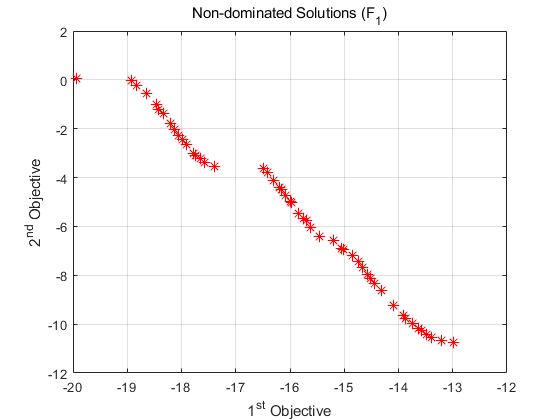

for it=1:MaxIt
    
    % Crossover
    popc=repmat(empty_individual,nCrossover/2,2);
    for k=1:nCrossover/2
        
        i1=randi([1 nPop]);
        p1=pop(i1);
        
        i2=randi([1 nPop]);
        p2=pop(i2);
        
        [popc(k,1).Position, popc(k,2).Position]=Crossover(p1.Position,p2.Position);
        
        popc(k,1).Cost=CostFunction(popc(k,1).Position);
        popc(k,2).Cost=CostFunction(popc(k,2).Position);
        
    end
    popc=popc(:);
    
    % Mutation
    popm=repmat(empty_individual,nMutation,1);
    for k=1:nMutation
        
        i=randi([1 nPop]);
        p=pop(i);
        
        popm(k).Position=Mutate(p.Position,mu,sigma);
        
        popm(k).Cost=CostFunction(popm(k).Position);
        
    end
    
    % Merge
    pop=[pop
         popc
         popm]; %#ok
     
    
    % Non-Dominated Sorting
    [pop, F]=NonDominatedSorting(pop);
    
     % Calculate Crowding Distance
     pop=CalcCrowdingDistance(pop,F);

    if (length(F) > 3) && (length(F{1}) < nPop * 0.9 )

        % Sort Population
        pop=SortPopulation(pop, 0);

        % Truncate
        pop=pop(1:nPop);


        % Non-Dominated Sorting
        [pop, F]=NonDominatedSorting(pop);

        % Calculate Crowding Distance
        pop=CalcCrowdingDistance(pop,F);

        % Sort Population
        [pop, F]=SortPopulation(pop, 0);
    else
        % Jam
        rou = it / MaxIt * ( rouMax - rouMin) + rouMin;
        
        pop = CalcGDRegressDistance(pop, Info);
        pop = CalcFSorting(pop, rou);
        
        [pop, F]= SortPopulation(pop, 1);
        
        % Truncate
        pop = pop(1:nPop); 
        
        % Non-Dominated Sorting
        [pop, F]=NonDominatedSorting(pop);
        
        % Calculate Crowding Distance
        pop=CalcCrowdingDistance(pop,F);
        
        pop = CalcGDRegressDistance(pop, Info);
        pop = CalcFSorting(pop, rou);
        
        % Sort Population by new regulation 
        [pop, F]= SortPopulation(pop, 1);
    end
 
    % Store F1
    F1=pop(F{1});
     
    % Show Iteration Information
    disp(['Iteration ' num2str(it) ': Number of F1 Members = ' num2str(numel(F1))]);
    
    % Plot F1 Costs
    figure(1);
    PlotCosts(F1);
    pause(0.01);
    
end

## Results